# ECE1150 ASSIGNMENT2 YINHAO QIAN

%please ignore this block
answer = @(num,unit) fprintf(" ANSWER: %f [%s] \n",num,unit);
question = @() eval("clearvars -except answer question");

# Q1_A

question();
lambda = 1;%[packets/s] average arrival rate
mu = 1.5;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: 1.333333 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 0.666667 [s] 


# Q1_B

Please refer to ./assi2_subm/assi2_q1b_simu.slx for source code infomation:

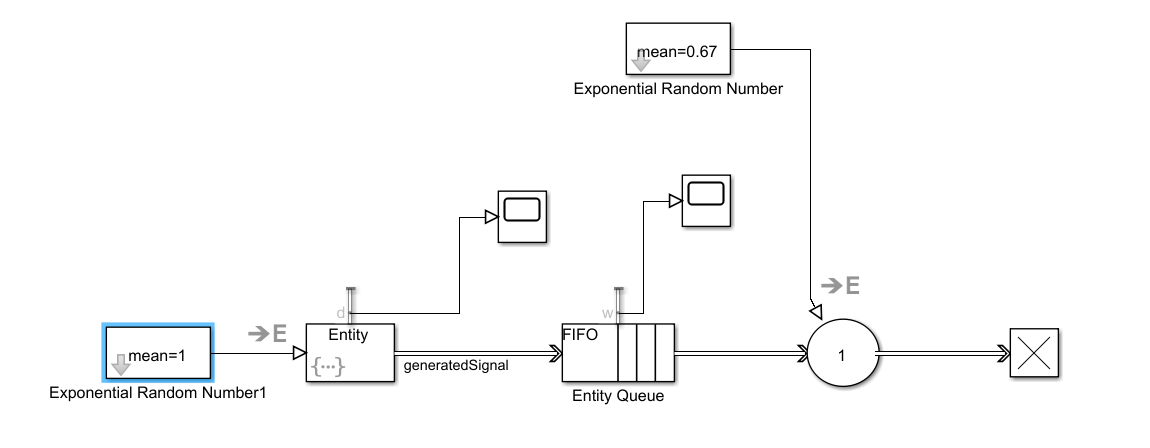

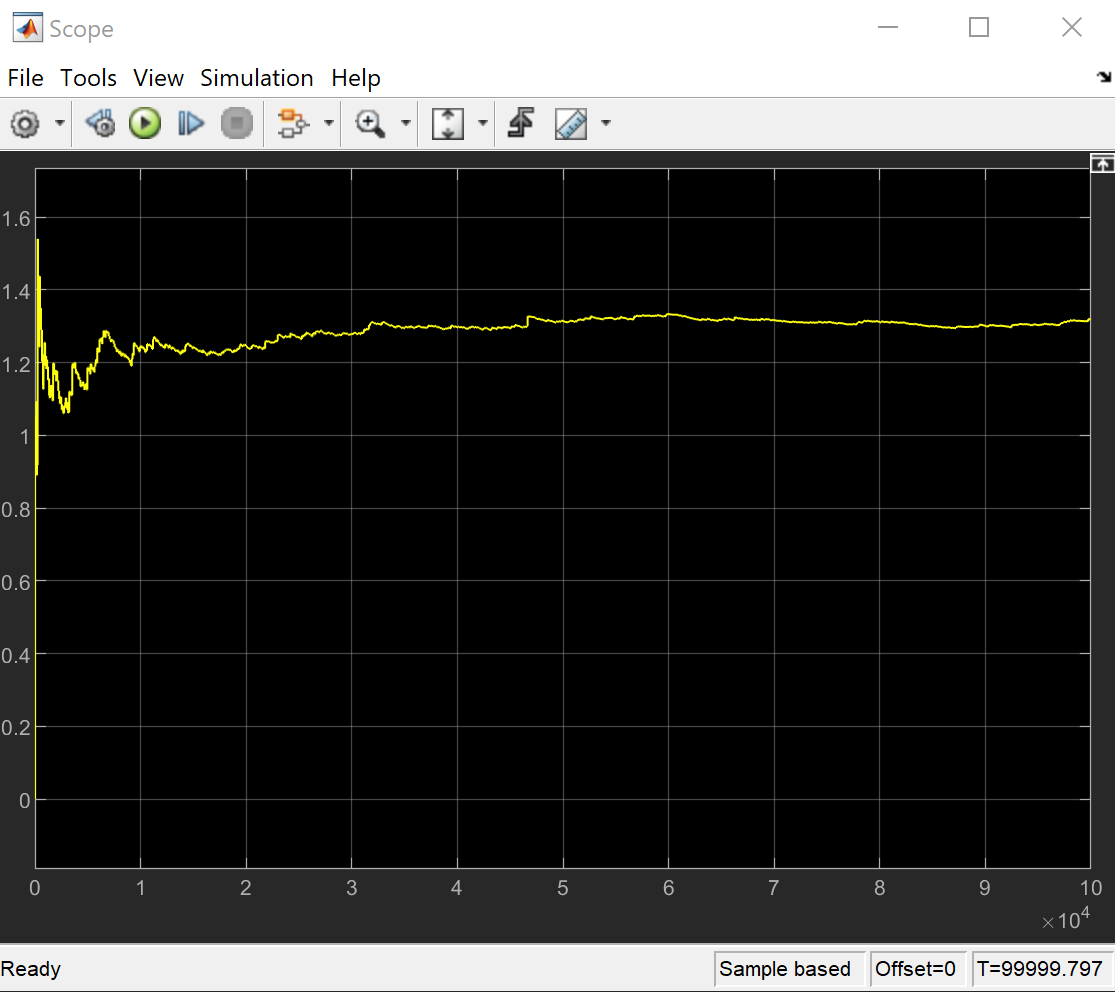

We can tell that the average waiting time is around 1.3333 [s], which matches with our calculation.

# Q1_C

## Stable Case:

Let's try another stable case with average arrival rate halved, which means the average arrival time doubled:

question();
lambda = 0.5;%[packets/s] average arrival rate
mu = 1.5;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: 0.333333 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 0.666667 [s] 


Please refer to ./assi2_subm/assi2_q1c1_simu.slx for source code infomation:

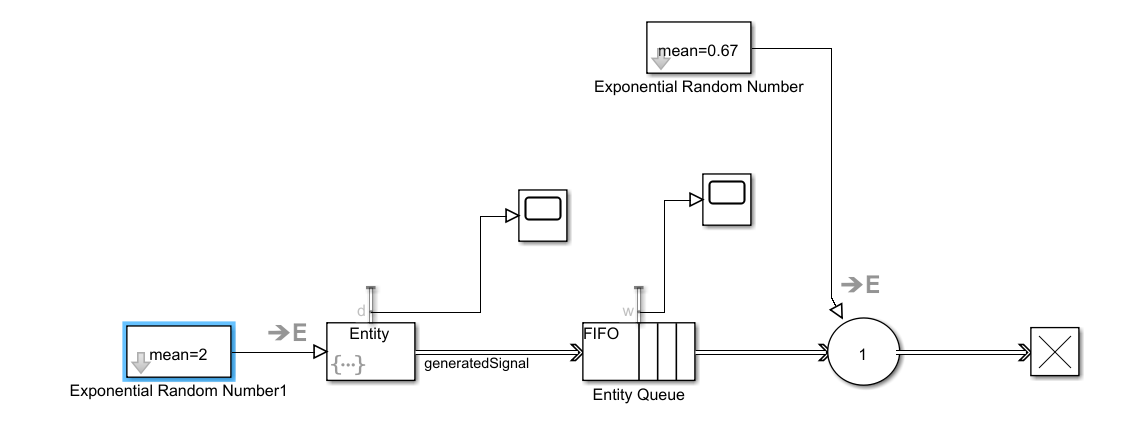

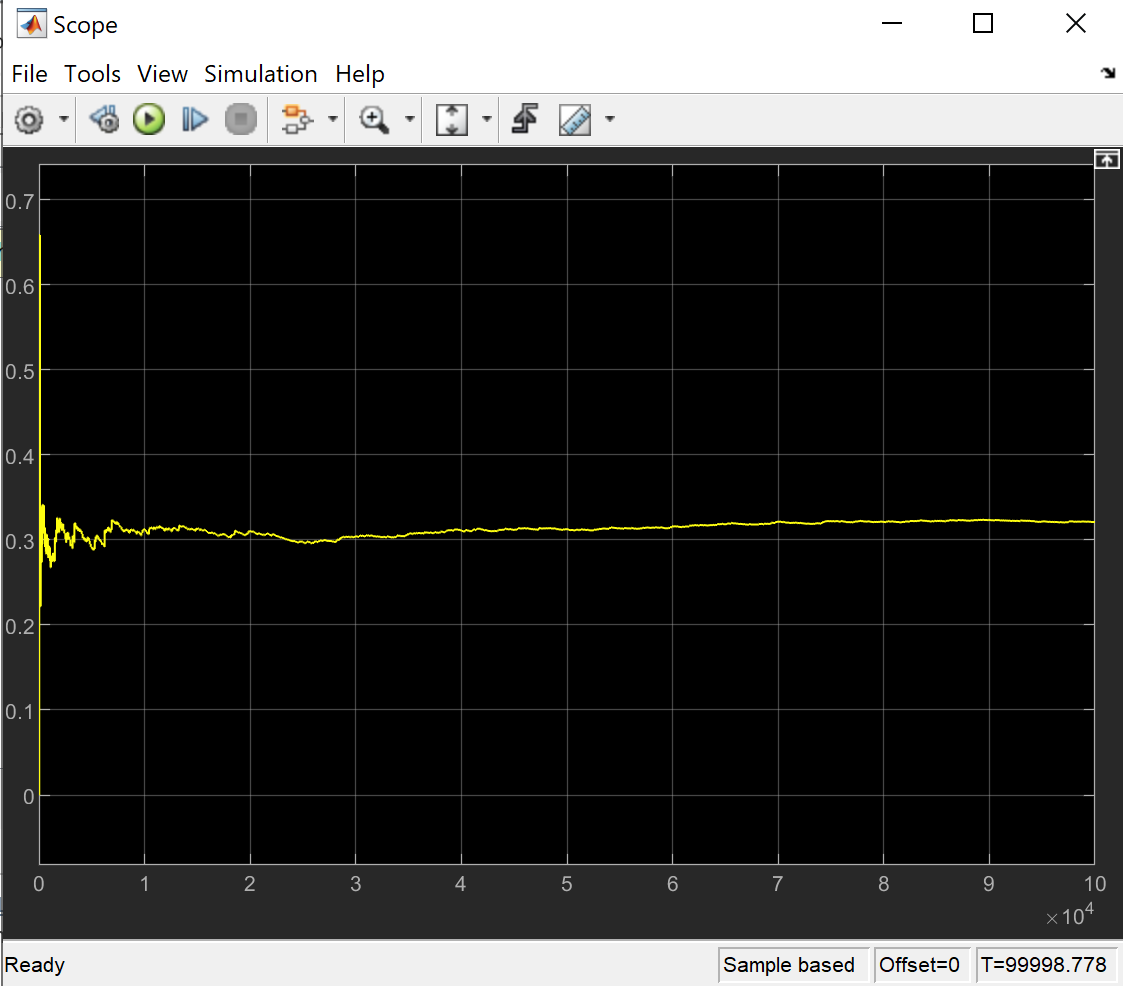

We can tell that the average waiting time is around 0.3333 [s], which matches with our calculation.

## Unstable Case:

Let's make the average service rate very low, and now it takes 10 secs on average to merely serve one packet:

question();
lambda = 1;%[packets/s] average arrival rate
mu = 0.1;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: -11.111111 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 10.000000 [s] 


Please refer to ./assi2_subm/assi2_q1c2_simu.slx for source code infomation:

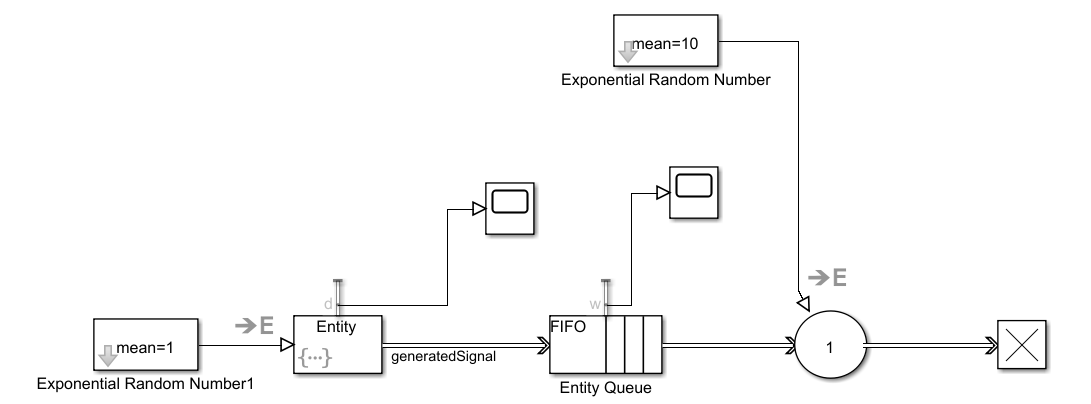

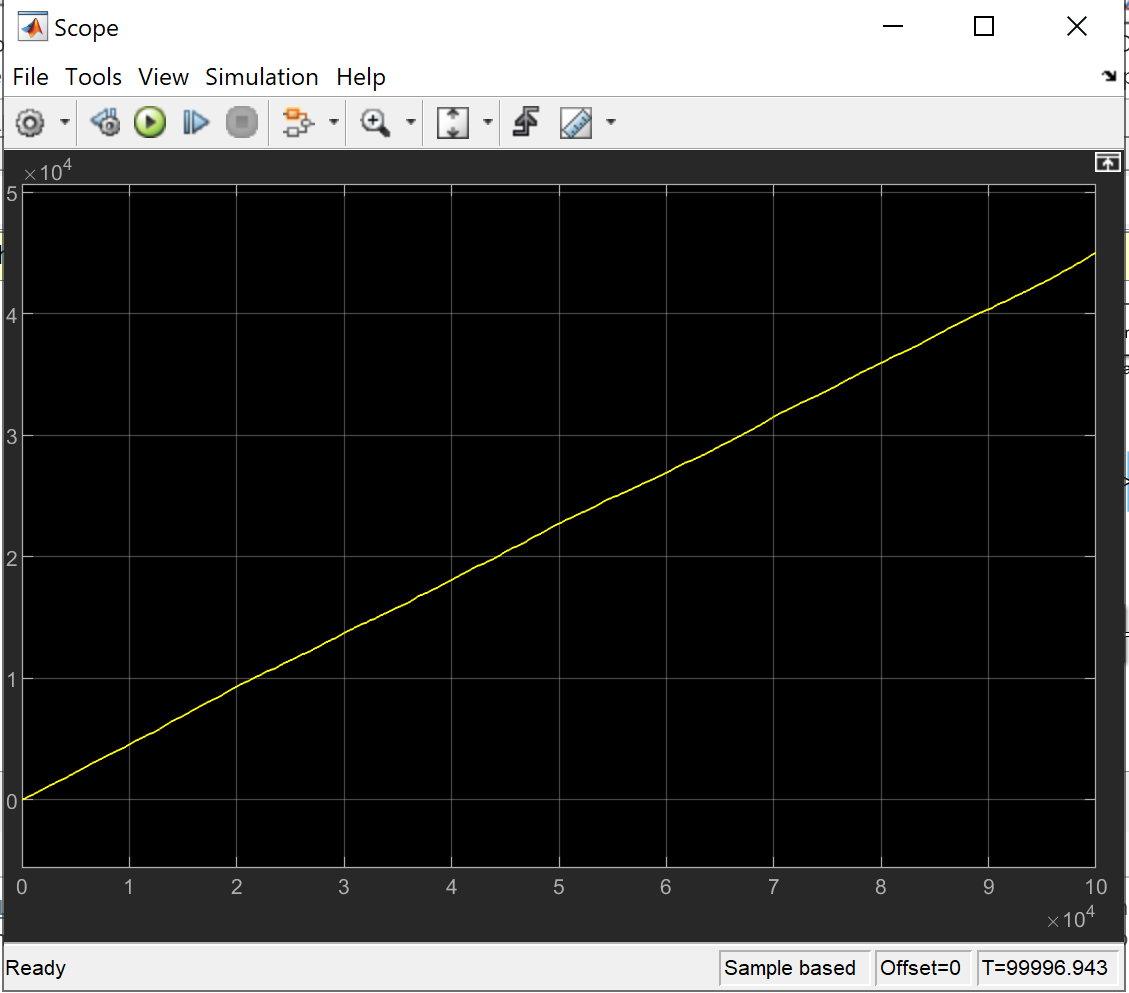

We can observe the analytical calculation is unable to give us a realistic answer, because the average waiting time being unstable makes the overflow of quene, yet we have set our capacity to be infinite. Now let's see what will happen if a capacity limit is placed:

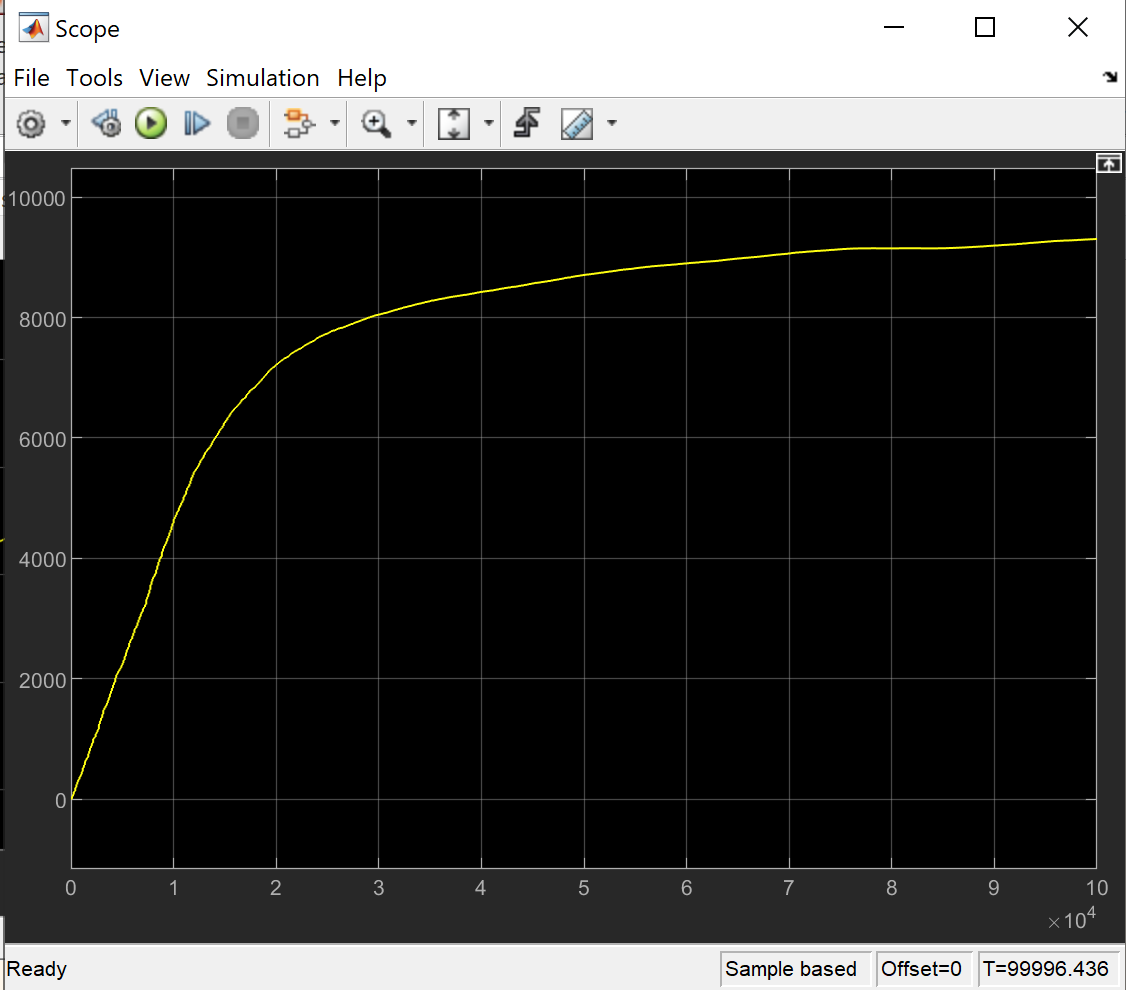

# Q2

Ok so I'm not actually sure if part A, B, and C refers to the same question, but that's what I understood:((

## Analytical Calculations:

question();
lambda = [9,3,4];%[packets/s] average arrival rate for each CHANNEL
mu = [14,12];%[packets/s] average service rate for each queue
p = 1/4;%[] splitting rate
lambda = [p*(lambda(1)+lambda(2))+lambda(3),(1-p)*(lambda(1)+lambda(2))];%[packets/s] average arrival rate for each QUEUE!!
D = 1./(mu-lambda);%[s] average delay 
W = D-1./mu;%[s] average waiting time
answer(1./mu(1),"s");%[s] average service time for queue A

 ANSWER: 0.071429 [s] 


answer(W(1),"s");%[s] average wait time for queue A

 ANSWER: 0.071429 [s] 


answer(1./mu(2),"s");%[s] average service time for queue B

 ANSWER: 0.083333 [s] 


answer(W(2),"s");%[s] average wait time for queue B

 ANSWER: 0.250000 [s] 


## Simulink Simulations:

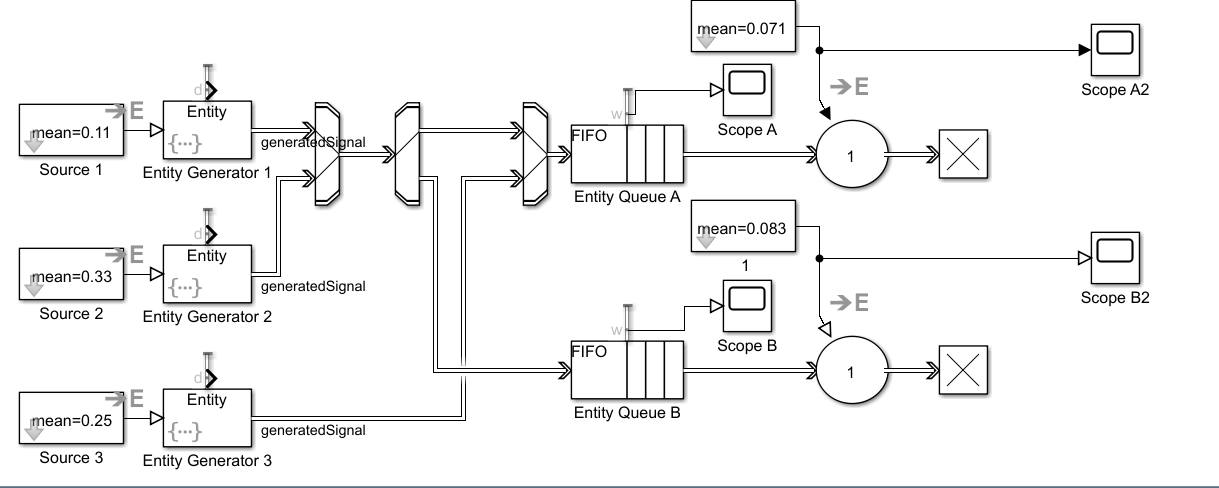

### Wait time:

For Queue A:

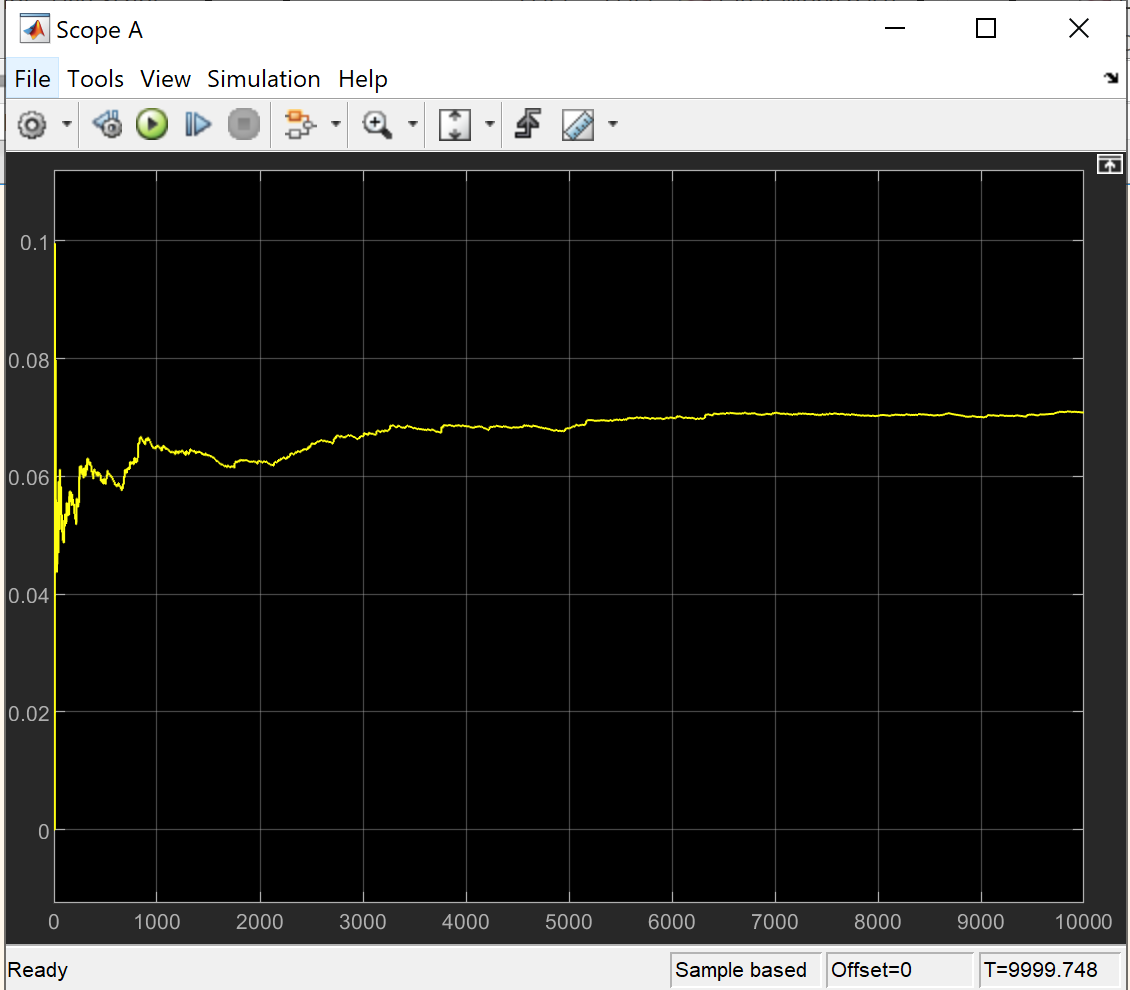

For Queue B:

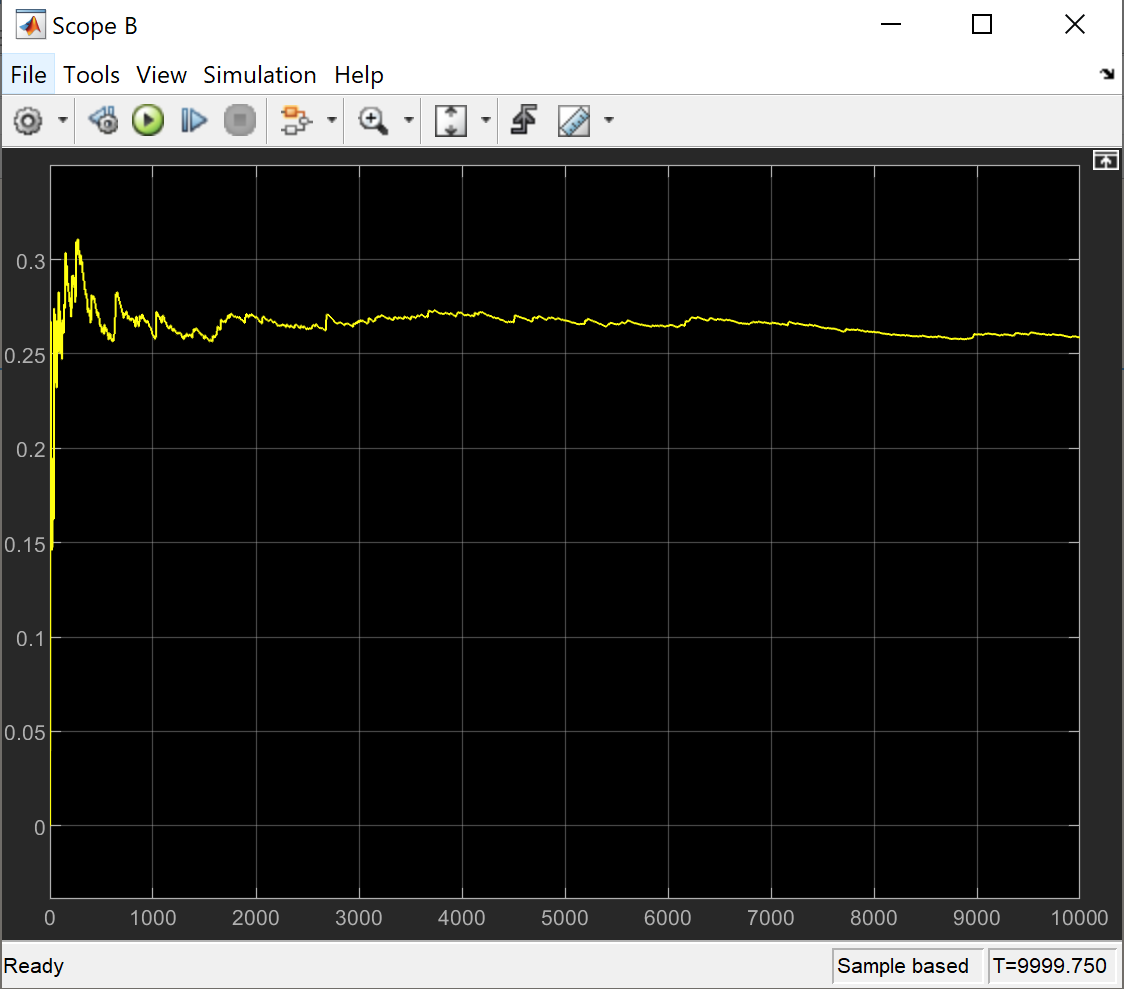

### Service Rate (Used to conclude Average Service Time):

For Queue A:

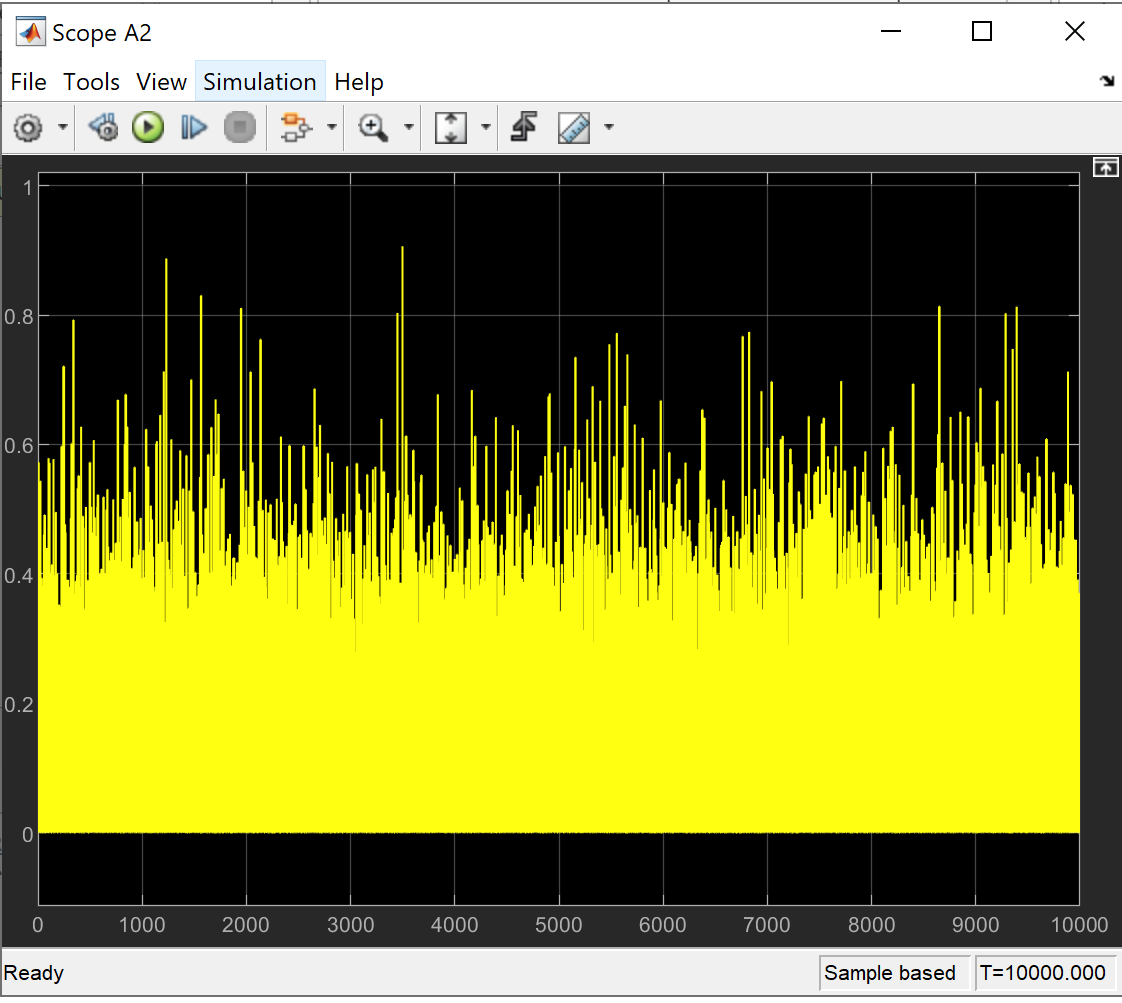

For Queue B:

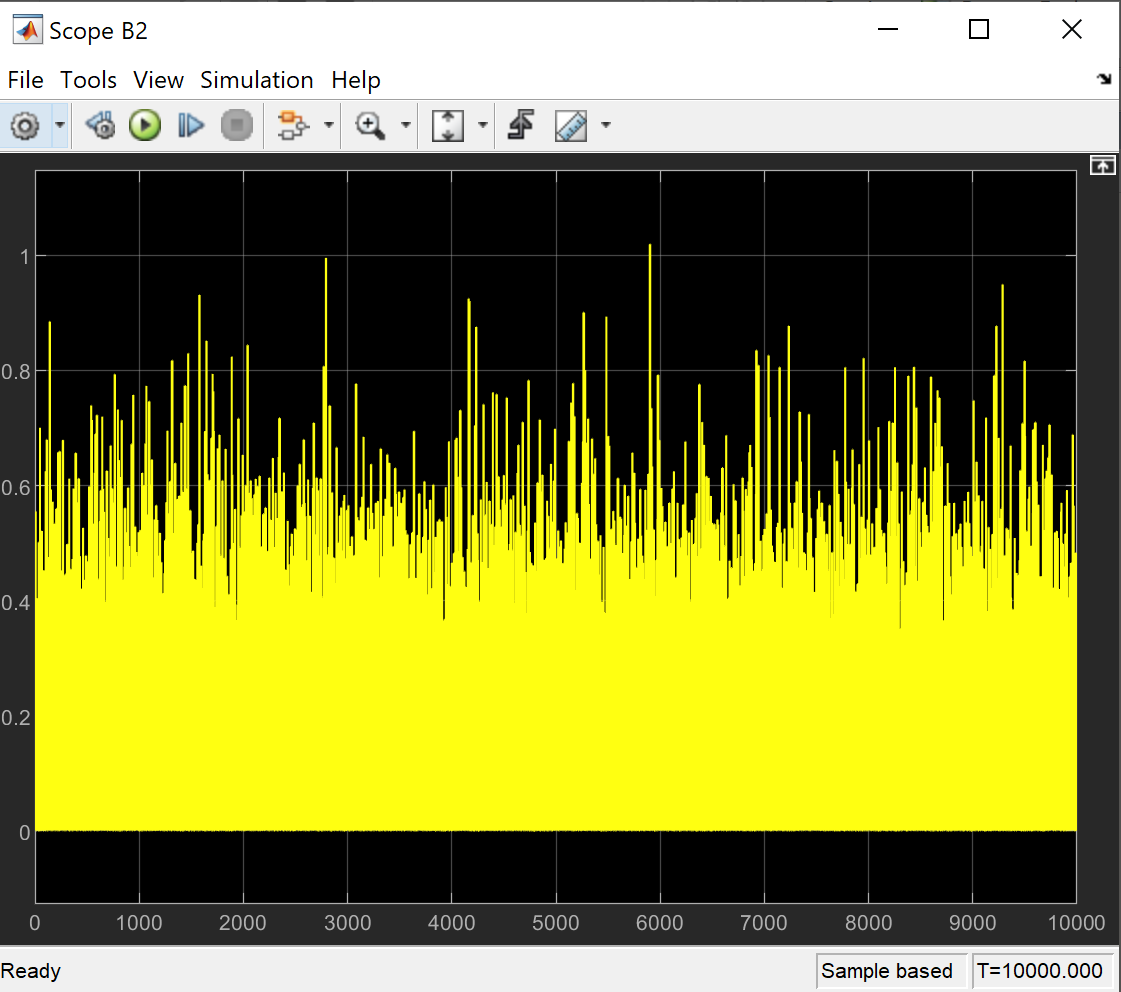

To observe the average serving time, simply take the reciprocal of the average serving rate, and we can see they match with our preassumptions. 

# Q3_A

In order for the quene not to be overflowed, we need to make sure that the average inter-arrival time and average service time:

#### 
$$\frac{1}{\lambda }\le \frac{1}{\mu }$$


# Q3_B

I would assume the variables mentioned in the question refers to the average arrival time and service time, so in this case, it would be:

#### 
$$A_t \le S_t$$


# Q4_A

Although it is specified in the question that the service time for one byte of data is a constant time, but the service time for one PACKET is not constant, since the packet length is exponentially distributed:

question();
serviceTime = 200*125e-6%[s] average service time

serviceTime = 0.0250

mu = 1/serviceTime;%[packet/s] average service rate
answer(mu,"s");

 ANSWER: 40.000000 [s] 


# Q4_B

lambda = 30;%[packet/s] average arrival rate
D = 1/(mu-lambda);%[s] average total delay
answer(D,"s");

 ANSWER: 0.100000 [s] 


# Q4_C

W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: 0.075000 [s] 


# Q4_D

N_q = D*lambda;%[] average number of packets in the queue
answer(N_q,"s");

 ANSWER: 3.000000 [s] 


# Q5

5. Application layer - specifies user needs and creates messages

4. Transport layer - segment and reassemble data segments, and sometimes do transfer and speed matching.

3. Network layer - identify and locate destination and deliver datagrams.

2. Data-link layer - deliver reliably frames over a link and control errors.

1. Physical layer - signal and move individual bits based on medium

# Q6

question();
lambda = 28*36;%[packets/s] average arrival rate total
mu = 24*64;%[packets/s] average service rate total
D = 1/(mu-lambda);%[s] average total delay
answer(D,"s");

 ANSWER: 0.001894 [s] 


export('assi2_subm.mlx','assi2_subm.pdf');

# END OF DOCUMENT